# Uniform LSUN 

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2022a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2022, Shogo MURAMATSU, All rights reserved.

clc, clear
isVisible = ~true;
support.fcn_download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

img = im2double(rgb2gray(imread("./data/kodim01.png")));

% rblk = imd';
% nblocks = 9;
% blk = im2col(rblk,[14 14] ,'distinct')
nof = 1;
ky = 2*nof+1; % # of overlapping blocks (odd number)
kx = 2*nof+1;
disp([ky kx])

     3     3



blksz = [4 4]; % Block size
% # of coeffs
nCoefs = 4;

Local block PCA

% % Create Sub-images
% s_img = createsubimg(blk);
[szy,szx] = size(img);
lbpcaimg = zeros(szy,szx);
for iBlkCol = 1:szx/blksz(2)
    for iBlkRow = 1:szy/blksz(1)
        % Extract ky x kx blocks
        subblks = fcn_extract_blks_(img,[iBlkRow,iBlkCol],blksz,[ky,kx]);
        % Reshape
        colblks = im2col(subblks,blksz,"distinct");
        % PCA
        %Vpca = pca(colblks.')
        mu = mean(colblks,2);
        colblkszm = colblks - mu;
        C = cov(colblkszm.');
        [~,S,V] = svd(C,"econ");
        [~,idxS] = sort(diag(S),"descend");
        V = V(:,idxS(1:nCoefs));
        %norm(Vpca - Vsvd,'fro')
        % Approxiamtion
        targetblk = fcn_extract_blks_(img,[iBlkRow,iBlkCol],blksz,[1 1]);
        targetblk = reshape(V*V.'*(targetblk(:)-mu)+mu,size(targetblk));
        % Place block
        lbpcaimg = fcn_place_blks_(lbpcaimg,targetblk,[iBlkRow,iBlkCol],blksz);
    end
end

Global block PCA

% Reshape
colblks = im2col(img,blksz,"distinct");
% PCA
%Vpca = pca(colblks.')
mu = mean(colblks,2);
colblkszm = colblks - mu;
C = cov(colblkszm.');
[~,S,V] = svd(C,"econ");
[~,idxS] = sort(diag(S),"descend");
V = V(:,idxS(1:nCoefs));
%norm(Vpca - Vsvd,'fro')
% Approxiamtion
gbpcaimg = col2im(V*V.'*(colblks-mu)+mu,blksz,size(img),"distinct");


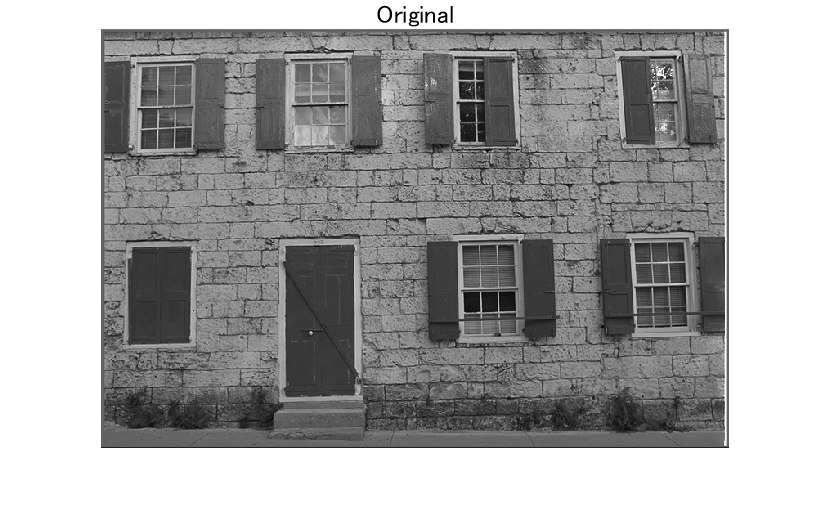


imshow(img)
title("Original")

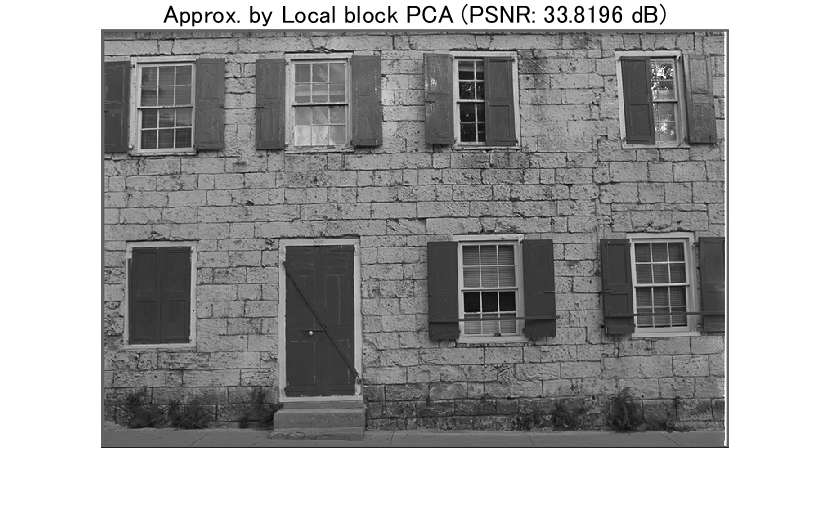


imshow(lbpcaimg)
title("Approx. by Local block PCA (PSNR: " + num2str(psnr(img,lbpcaimg))+" dB)")

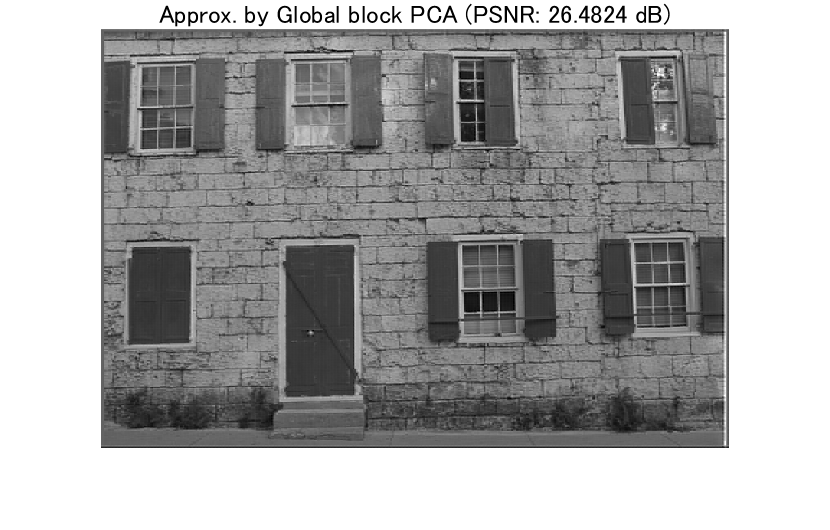


imshow(gbpcaimg)
title("Approx. by Global block PCA (PSNR: " + num2str(psnr(img,gbpcaimg))+" dB)")

## Locally Structured Unitary Network (LSUN) for 2-D Grayscale image

% Decimation factor (Strides)
stride = blksz; % [My Mx]

% Number of overlapping blocks
ovlpFactor = [ky kx];

% Number of iterations
nIters = 3;

% Standard deviation of initial angles
stdInitAng = pi/6;

% No DC-leakage
noDcLeakage = true;

Setting of optimization step

opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    ...'InitialLearnRate',0.0100,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,...
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',8,...20,...
    'MiniBatchSize',8,...64,...
    'Verbose',1,...
    'VerboseFrequency',16,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','none',...'training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1


## Bivariate lattice-structure of filter banks 

As a base system for LSUN, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【Example】For $P/2=3$, a parametric orthonormal matrix $\mathbf{U}(\mathbf{\theta},\mathbf{\mu})$ can be constructed by 

        
$$\mathbf{U}(\mathbf{\theta},\mathbf{\mu}) \colon = \left(\begin{array}{cc} \mu_1 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right)
%
\left(\begin{array}{ccc} 
 1 & 0 & 0 \\
0 & \cos\theta_2& -\sin\theta_2 \\ 
0 & \sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & -\sin\theta_1  \\ 
 0 & 1 & 0 \\
\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_0& -\sin\theta_0 & 0 \\ 
\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right),$$


        
$${\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & \sin\theta_1  \\ 
 0 & 1 & 0 \\
-\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right),$$


where $\mathbf{\theta}\in\mathbb{R}^{(P-2)P/8}$ and $\mathbf{\mu}=\{-1,1\}^{P/2}$. For the sake of simplification, the sign parameters $\mu_k$ are fixed to $-1$for $\mathbf{U}_n^{\{d\}}$ witn odd $n$, otherwise they are fixed to $+1$.

Partial differentiation can be, for examle, conducted as

        
$$\frac{\partial}{\partial \theta_1}{\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
-\sin\theta_1& 0 & \cos\theta_1  \\ 
 0 & 0 & 0 \\
-\cos\theta_1 & 0 &  -\sin\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right).$$


A locally-structured unitary network (LSUN) allows to change the parameters block by block.

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

### Definition of custom layers and networks 

Use a custom layer of Deep Learning Toolbox to implement Synthesis LSUN.

#### Definition of layers w/ Learnable properties

- Final rotation: $\mathbf{V}_{0,b}^T$ (tansacnet.lsun.lsunFinalRotationLayer)

- Intermediate rotation: ${\mathbf{V}_{n,b}^{\{d\}}}^T$ (tansacnet.lsun.lsunIntermediateRotationLayer)

#### Definition of layers w/o Learnable properties

- Bivariate inverese DCT (2-D IDCT): $\mathbf{E}_0^T=\mathbf{E}_0^{-1}$ (tansacnet.lsun.lsunBlockDctLayer)

- Vertical up extension: $\mathbf{Q}^T(z_\mathrm{v}^{-1})$ (tansacnet.lsun.lsunAtomExtensionLayer)

- Vertical down extension: $\bar{\mathbf{Q}}^T(z_\mathrm{v}^{-1})$  (tansacnet.lsun.lsunAtomExtensionLayer)

- Horizontal left extension: $\mathbf{Q}^T(z_\mathrm{h}^{-1})$ (tansacnet.lsun.lsunAtomExtensionLayer)

- Horizontal right extension: $\bar{\mathbf{Q}}^T(z_\mathrm{h}^{-1})$ (tansacnet.lsun.lsunAtomExtensionLayer)

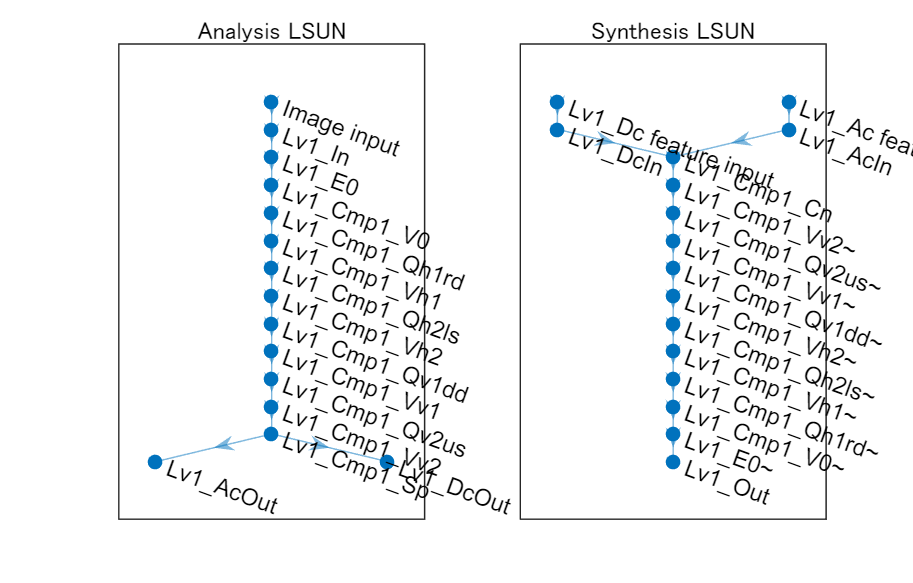

import tansacnet.lsun.*
analysislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synthesislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
figure(1)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')


% Construction of synthesis network.
analysisnet = dlnetwork(analysislgraph);

% Initialize
nLearnables = height(analysisnet.Learnables);
for iLearnable = 1:nLearnables
    if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
        analysisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~


synthesisnet = dlnetwork(synthesislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)

x = rand([szy szx],'single');
dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 4.4355e-09"



TODO: Parameter optimization and approximation

## Definitions of local functions

function y = fcn_extract_blks_(x,iBlk,blksz,k)
% Extend array x
ky = k(1);
kx = k(2);
iBlkRow = iBlk(1);
iBlkCol = iBlk(2);
padsz = [(ky-1)/2, (kx-1)/2].*blksz;
xx = padarray(x,padsz,"circular");
%
posy = (iBlkRow-1)*blksz(1)+1;
posx = (iBlkCol-1)*blksz(2)+1;
y = xx(posy:posy+ky*blksz(1)-1,posx:posx+kx*blksz(2)-1);
end

function y = fcn_place_blks_(y,blk,iBlk,blksz)
% Extend array x
iBlkRow = iBlk(1);
iBlkCol = iBlk(2);
posy = (iBlkRow-1)*blksz(1)+1;
posx = (iBlkCol-1)*blksz(2)+1;
y(posy:posy+blksz(1)-1,posx:posx+blksz(2)-1) = blk;
end
